file_path1 = 'C:\Users\gajapathy.s\Desktop\gps\walkingRTK.bag';




 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
 scatterplot(UN,UE)
 dat= [UN; UE]

dat =          0    0.3327    0.9731    1.4773    2.1594    2.7310    3.3462    3.9653    4.5959    5.2426    5.8076    6.3505    7.0537    7.6937    8.3430    8.9864    9.6200   10.2784   10.8735   11.5843   12.2042   12.8959   13.5775   14.2763   14.9512   15.6421   16.3442   17.0858   17.7584   18.4503   19.1344   19.8479   20.5498   21.2416   21.9951   22.7463   23.4979   24.2651   25.0085   25.7621   26.5546   27.3773   28.1041   28.8780   29.6246   30.3840   31.1722   31.9466   32.7321   33.5556
         0    0.6292    1.2608    1.8129    2.3086    2.8395    3.3581    3.8943    4.5029    5.0886    5.6870    6.2373    6.8241    7.4529    8.0472    8.6669    9.3050    9.9379   10.5835   11.2196   11.8787   12.5181   13.1408   13.7391   14.3412   15.0513   15.7406   16.3797   17.0261   17.6647   18.2918   18.9329   19.5857   20.2738   20.9528   21.5767   22.2655   22.9376   23.6044   24.3035   25.0249   25.7125   26.4240   27.0824   27.7630   28.5343   29.2387   29.8984   30.5109   

   
 p = polyfit(UN, UE, 1);

    y_fit = polyval(p, UN);
dat1= [UN;y_fit]

dat1 =          0    0.3327    0.9731    1.4773    2.1594    2.7310    3.3462    3.9653    4.5959    5.2426    5.8076    6.3505    7.0537    7.6937    8.3430    8.9864    9.6200   10.2784   10.8735   11.5843   12.2042   12.8959   13.5775   14.2763   14.9512   15.6421   16.3442   17.0858   17.7584   18.4503   19.1344   19.8479   20.5498   21.2416   21.9951   22.7463   23.4979   24.2651   25.0085   25.7621   26.5546   27.3773   28.1041   28.8780   29.6246   30.3840   31.1722   31.9466   32.7321   33.5556
    0.5325    0.8370    1.4233    1.8848    2.5092    3.0325    3.5956    4.1623    4.7396    5.3316    5.8488    6.3458    6.9895    7.5753    8.1697    8.7588    9.3388    9.9414   10.4862   11.1369   11.7044   12.3376   12.9615   13.6012   14.2190   14.8514   15.4942   16.1730   16.7887   17.4221   18.0483   18.7015   19.3440   19.9773   20.6671   21.3547   22.0427   22.7451   23.4256   24.1154   24.8409   25.5940   26.2593   26.9677   27.6512   28.3464   29.0679   29.7768   30.4959  

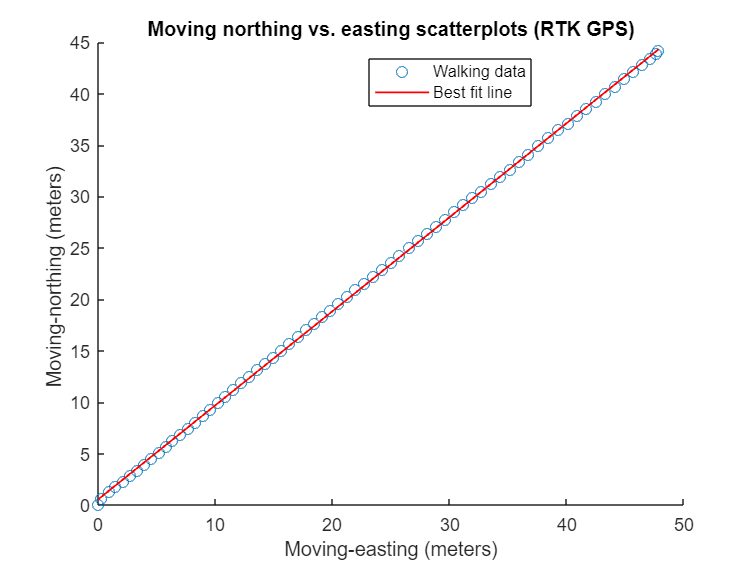



    hold on;
    plot(UN, y_fit, 'r-', 'LineWidth', 1, 'DisplayName', 'Line of Best Fit');
    hold off;

legend('Walking data','Best fit line')
 xlabel('Moving-easting (meters)');
 ylabel('Moving-northing (meters) ');
 title('Moving northing vs. easting scatterplots (RTK GPS)');
 
legend("Position", [0.48889,0.81433,0.21429,0.082143])

error=dat1-dat

error =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5325    0.2079    0.1625    0.0719    0.2006    0.1930    0.2375    0.2681    0.2368    0.2430    0.1617    0.1085    0.1654    0.1225    0.1225    0.0918    0.0338    0.0035   -0.0973   -0.0827   -0.1744   -0.1805   -0.1793   -0.1379   -0.1222   -0.1999   -0.2464   -0.2067   -0.2373   -0.2426   -0.2435   -0.2314   -0.2416   -0.2965   -0.2857   -0.2220   -0.2227   -0.1925   -0.1788   -0.1881   -0.1840   -0.1185   -0.1646   -0.1146   -0.1118   -0.1879   -0.1708   -0.1216   -0.0150 

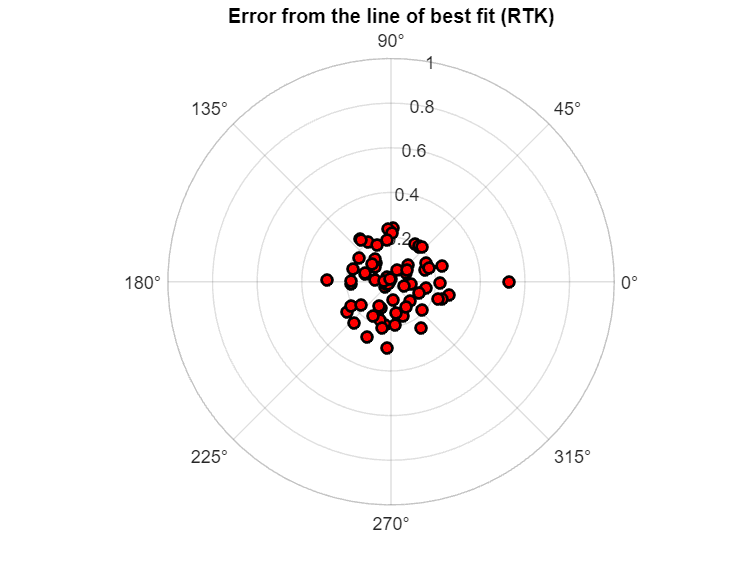



angles =UN * 2 * pi; 
magnitudes = error(2,:); 

polarplot(angles, magnitudes, 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'r', 'MarkerSize', 6, 'LineWidth', 1.5, 'DisplayName', 'Data Points');

title('Error from the line of best fit (RTK)');


rlim([0, 1]); 
rticks(0:0.2:1); 
thetaticks(0:45:315); 

grid on; 












  % 
  % hold on
  % 
  % [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= ex_bag(file_path2);
  % scatterplot(UN,UE);
  %   p = polyfit(UN, UE, 1);
  % 
  %   y_fit = polyval(p, UN);
  % 
  % 
  %   hold on;
  %   plot(UN, y_fit, 'r-', 'LineWidth', 1, 'DisplayName', 'Line of Best Fit');
  %   hold off;
% 
%
 % legend('Occluded walking ','Open walking')
hold off

a1 =    27.8390   27.3230   26.9090   26.5120   26.6580   26.6470   26.4700   26.5810   26.7460   26.9150   26.5860   26.2360   26.4500   26.1430   26.0260   25.8720   25.7470   25.6260   25.1780   25.0550   24.6520   24.6110   24.6400   24.6980   24.4730   24.2370   24.1270   24.0260   23.9190   23.7990   23.7210   23.5840   23.5100   23.4320   23.5040   23.5850   23.4750   23.4130   23.3550   23.2320   23.0490   22.9470   22.8190   22.8820   22.9020   22.8420   22.6620   22.5740   22.4800   22.3050


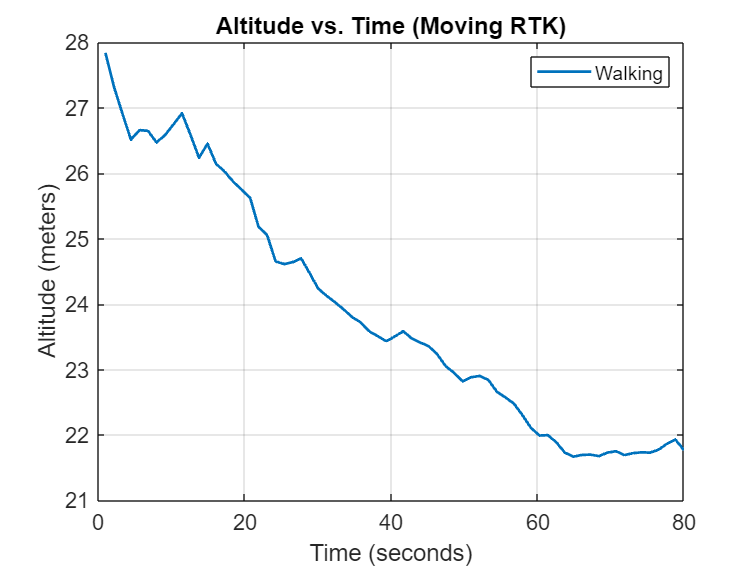


 alt(file_path1)

function []= alt(file_path1)

[lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
d1=delta_time;
a1=Alt

 altitude_(a1,delta_time,'r');
 hold on

function[]= altitude_(Alt,delta_time,c)

t = 1:1:delta_time;

t = linspace(min(t), max(t), length(Alt));


plot(t, Alt, 'MarkerFaceColor', 'r', 'LineWidth', 1.5);
% scatter(t, Alt, 'Marker', 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, 'SizeData', 100, 'LineWidth', 1.5, 'DisplayName', 'Data Points');

xlabel('Time (seconds)');
ylabel('Altitude (meters)');
title('Altitude vs. Time (Moving RTK)');
legend("Walking")

grid on;

set(gca, 'FontName', 'Arial', 'FontSize', 12);
set(gcf, 'Color', 'w'); 

end
end

function []=scatterplot(UE,UN,c)
scatter(UE, UN);
end




function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1)
Alt=0;
lat=0;
long=0;
Alt=0;
UtmE=0;
UtmN=0;
delta_time=0;

bag = rosbag(file_path1);
bSel = select(bag,'Topic','/rtk_gnss');
msgStructs = readMessages(bSel,'DataFormat','struct');

len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;

for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Latitude;
long(i)=gps.Longitude;
Alt(i)=gps.Altitude;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;

 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H=gps.Hdop;
latD=gps.LatitudeDir;
lonD=gps.LongitudeDir;

end

end




function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= ex_bag(file_path2)

bag = rosbag(file_path2);
bSel = select(bag,'Topic','/wire');
msgStructs = readMessages(bSel,'DataFormat','struct');
len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;


for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Lat;
long(i)=gps.Lon;
Alt(i)=gps.Alt;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;
 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H=gps.Hdop;

end


end


















































